# ปัญหาวันที่ 2

## เป้าหมาย

- สามารถระบุตำแหน่งของ stamping event ได้

- สามารถจำแนก stamping event ได้ (N/F)

- สามารถอธิบายแนวทางในการหาตำแหน่ง event การตัด segment และการจำแนก event ได้

## ข้อกำหนด

- ใช้ไฟล์ที่อยู่ใน folder Day2 ในการ train model โดยต้องตัดเองและเลือกความยาวในการตัดเอง

## ผลลัพธ์ที่ต้องการ

- โปรแกรมจะอ่านไฟล์ที่กำหนด แล้วแสดงผลลัพธ์เป็นตำแหน่งของ event และสถานะเป็น N (normal) หรือ F (faulty) บรรทัดละ event

- ตำแหน่งของ event จะเป็นลำดับของ sample นับตั้งแต่พบสัญญาณ SYNC โดยอนุญาตให้คลาดเคลื่อนได้ +/- 14400 sample (0.3 วินาที)

- รูปแบบการแสดงผลคล้ายดังนี้

102230 N

197740 F

275941 F

...

## โครงโปรแกรม

สามารถเขียนใหม่ได้ทั้งหมด ไม่จำเป็นต้องใช้ตามนี้

ตอนตรวจขั้นสุดท้าย จะต้องเปลี่ยนชื่อไฟล์ด้านล่างนี้ให้เป็นไฟล์ที่กำหนด

load('net.mat')
load('classNames.mat')

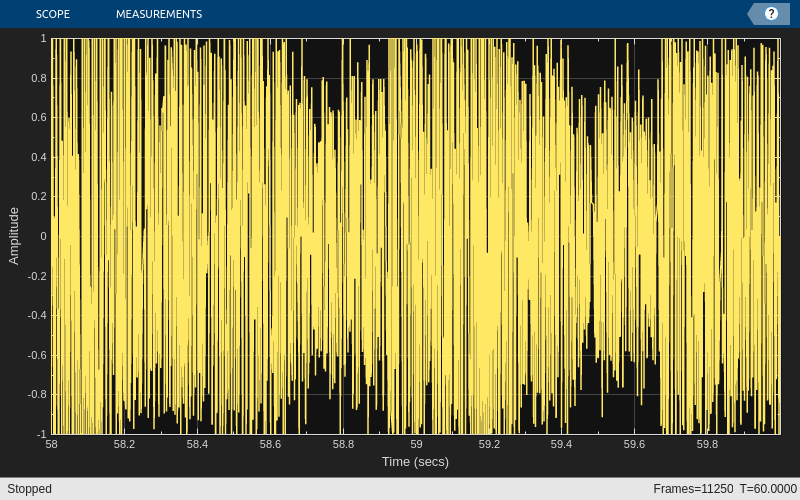

    
results = {}; % Create an empty cell array to store results

rowIndex = 1; % Initialize a row index for saving data

frameLength = 256;

% Using dsp.AudioFileReader
fileReader = dsp.AudioFileReader('Day2\Day2.wav', 'SamplesPerFrame', frameLength);
Fs = fileReader.SampleRate;

deviceWriter = audioDeviceWriter('SampleRate', Fs); % ส่งออกทีละ frame

scope = timescope('SampleRate', Fs, 'TimeSpan', 2, 'BufferLength', Fs * 2, ...
                  'YLimits', [-30, -10], 'TimeSpanOverrunAction', 'scroll');

bufferLength = round(5.0 * Fs);
audioBuffer = zeros(1, bufferLength);
bufferPosition = 1;
audioPositionSinceSync = 1;

maxPeak = 0.0;
startThreshold = db2mag(-30);

% Wait for SYNC signal (sinusoid with amplitude larger than -30 dBFS)
while ~isDone(fileReader)
    signal = fileReader(); % read a new frame
    if max(signal) > startThreshold
        maxPeak = max(signal);
        break;
    end
end

while ~isDone(fileReader)
    signal = fileReader(); % read a new frame

    % Adaptive normalization (-1, 1)
    signalPeak = max(abs(signal));
    if signalPeak > maxPeak
        maxPeak = signalPeak;
    end
    signal = signal / maxPeak; % scale the signal towards 1.0

    % Handle audio buffer
    frameLength = length(signal);
    emptyLength = bufferLength - bufferPosition + 1;
    % Make space for the new frame 
    if emptyLength < frameLength
        moveOffset = frameLength - emptyLength;
        audioBuffer(1:bufferPosition-moveOffset-1) = audioBuffer(moveOffset+1:bufferPosition-1);
        bufferPosition = bufferPosition - moveOffset;
    end
    % Fill in the buffer with the new frame
    audioBuffer(bufferPosition:bufferPosition+frameLength-1) = signal;
    bufferPosition = bufferPosition + frameLength;
    audioPositionSinceSync = audioPositionSinceSync + frameLength;

    % Process audio in the buffer (event detection)
    shortWinLength = round(0.3 * Fs);
    shortRMS = dsp.MovingRMS(shortWinLength);

    env1 = shortRMS(signal);
    threshold1 = mean(env1) + 1.99 * std(env1);
    peakIndices = find(env1 > threshold1);
    audioFFT = abs(fft(signal, 512))';

    % Segment, classify, and report results
    if ~isempty(peakIndices)
        scores = minibatchpredict(net, audioFFT, SequencePaddingDirection="left");
        predictedLabel = scores2label(scores, classNames);
        fprintf("%s, %s\n", num2str(audioPositionSinceSync), char(predictedLabel));

        results{rowIndex, 1} = audioPositionSinceSync;
        results{rowIndex, 2} = char(predictedLabel);
        rowIndex = rowIndex + 1;
    end

    % deviceWriter(signal);
    % scope(signal);
    % scope(mag2db(env1));
end

resultsTable = cell2table(results, 'VariableNames', {'Stamping Event', 'Predicted'});
writetable(resultsTable, 'predictions.xlsx'); % Save as predictions.xlsx

release(scope);
release(fileReader);
% release(deviceReader);
release(deviceWriter);
